% Wczytanie przygotowanych danych
load exps

## Dane zalogowane

Dane zalogowane podczas eksperymentu zostały przygotowane za pomoca skryptu `loadAndprepareData.m` i zapisaane jako struktura `exps`. Poszczególne pola struktury exps oznaczają:

- `data` - tablica z zalogowanymi i przygotowanymi danymi

- `dt` - stała czasowa

- `f` - częstotliwość próbkowania, logowania danych

- `filter_cut_off` - częstotliwość zastosowanego filtra

- `ackermanParams` - struktura z danymi EVE.

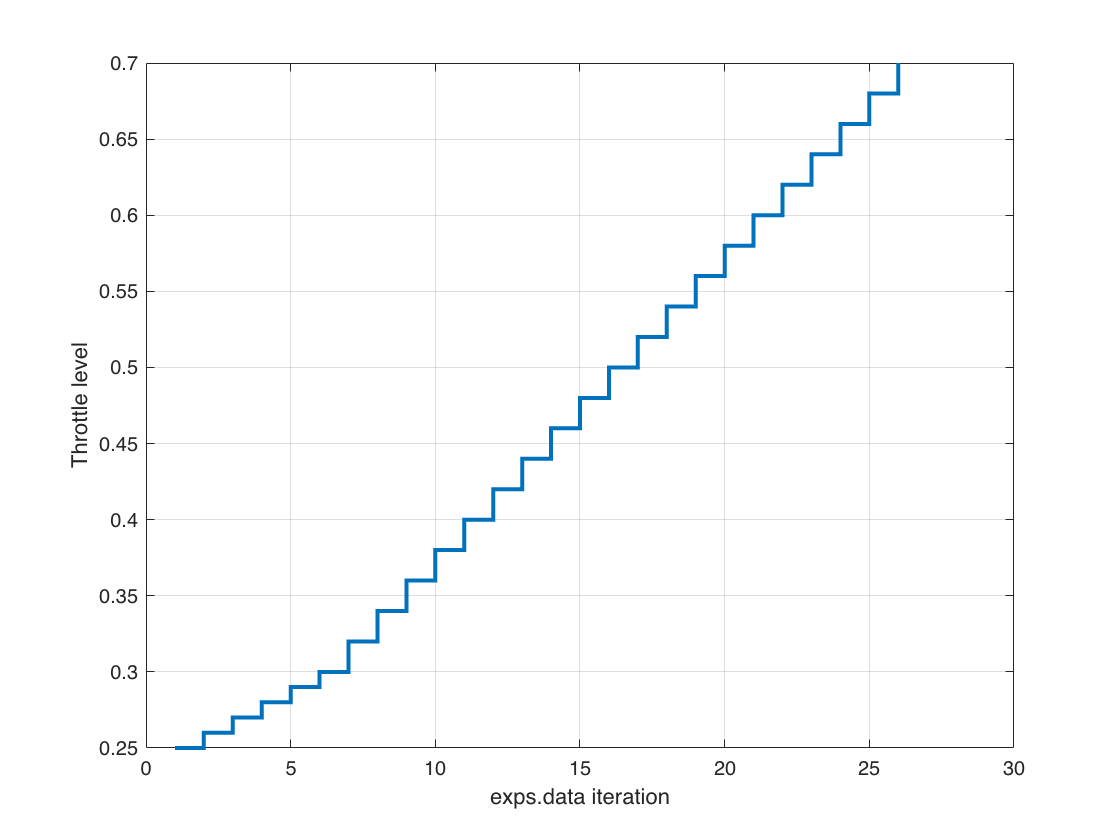

figure;
throttle = zeros(1, length(exps.data));
for i=1:1:length(exps.data)
    throttle(i) = exps.data{i}.throttle(100);
end
stairs(1:1:length(exps.data), throttle, 'LineWidth', 2);
xlabel('exps.data iteration');ylabel('Throttle level');grid;

## Dane do identyfikacji

Analizując dane do identyfikacji przyjmujemy dane z zakresu od 4-14. 

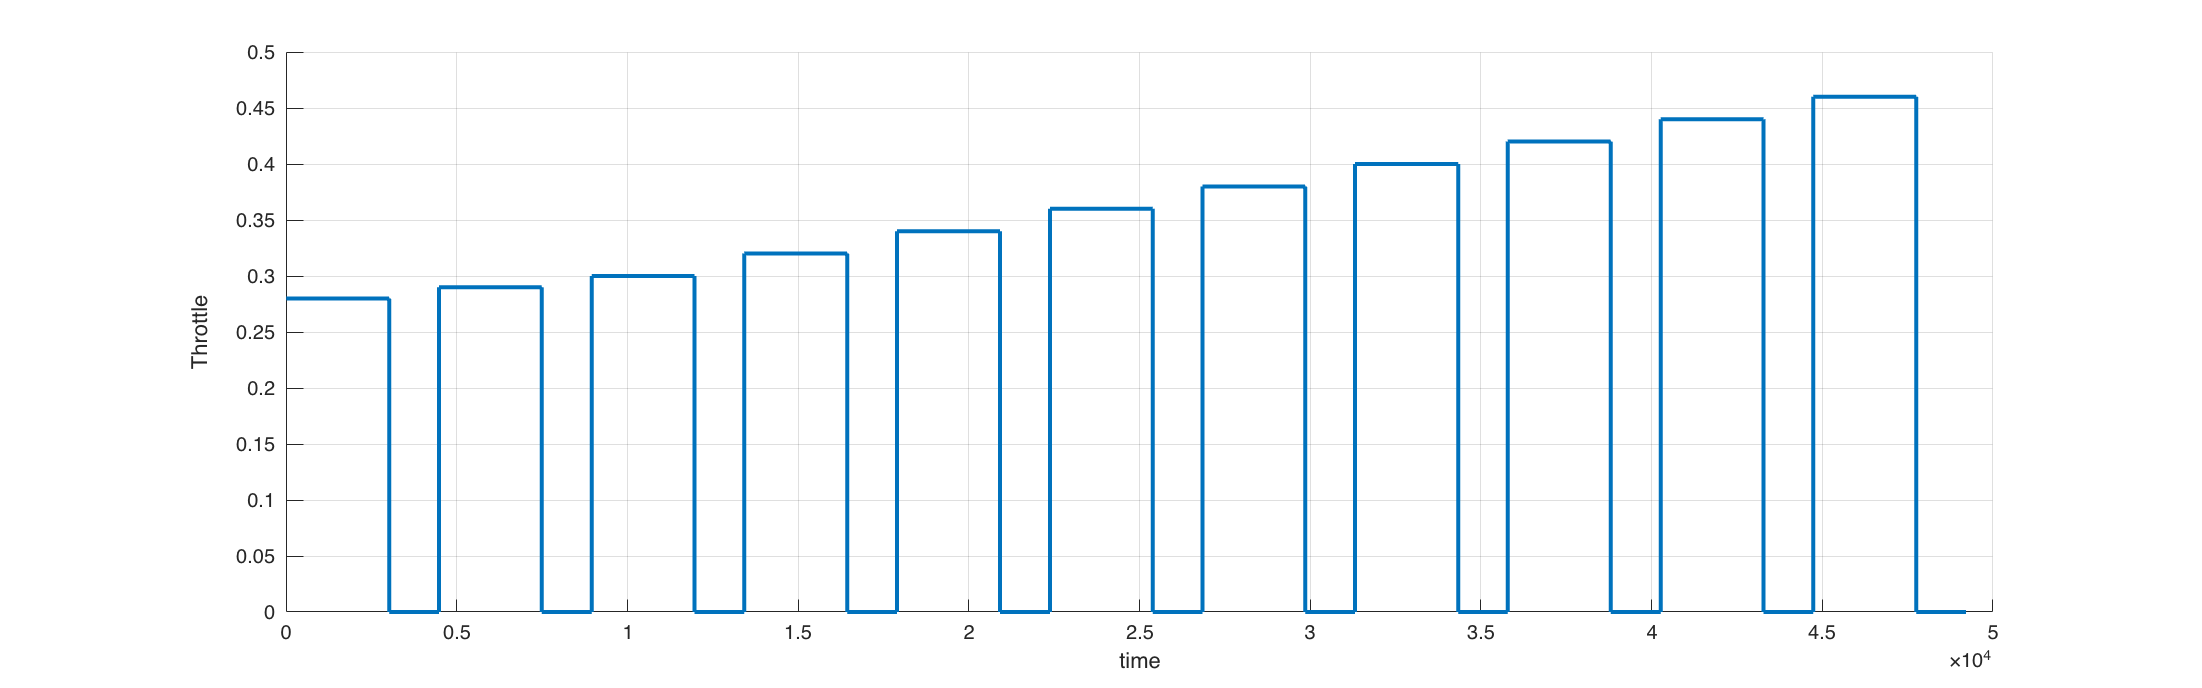

inputI = 4 : 1 : 14;

exps.ident.u = [];
exps.ident.y = [];
for i = inputI,
    exps.ident.u = [exps.ident.u exps.data{i}.throttle'];
    exps.ident.y = [exps.ident.y exps.data{i}.vel'];
end

figure('Units','normalized','Position',[0 0 1.0 .5]);
hold on;grid;stairs(exps.ident.u, 'LineWidth', 2);ylabel('Throttle');xlabel('time');hold off;

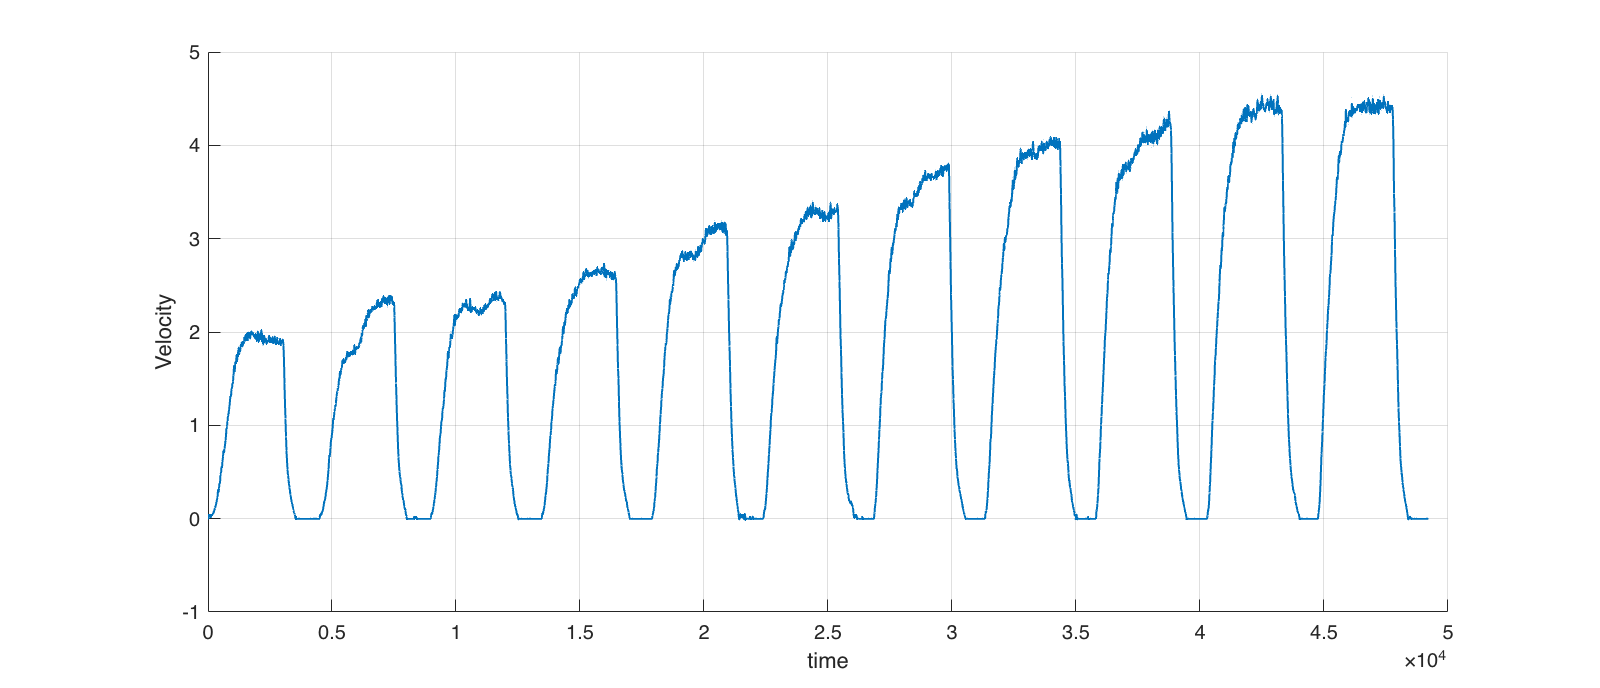

figure('Units','normalized','Position',[0 0 1.0 .5]);
hold on;grid;plot(exps.ident.y, 'LineWidth', 1);ylabel('Velocity');xlabel('time');hold off; 

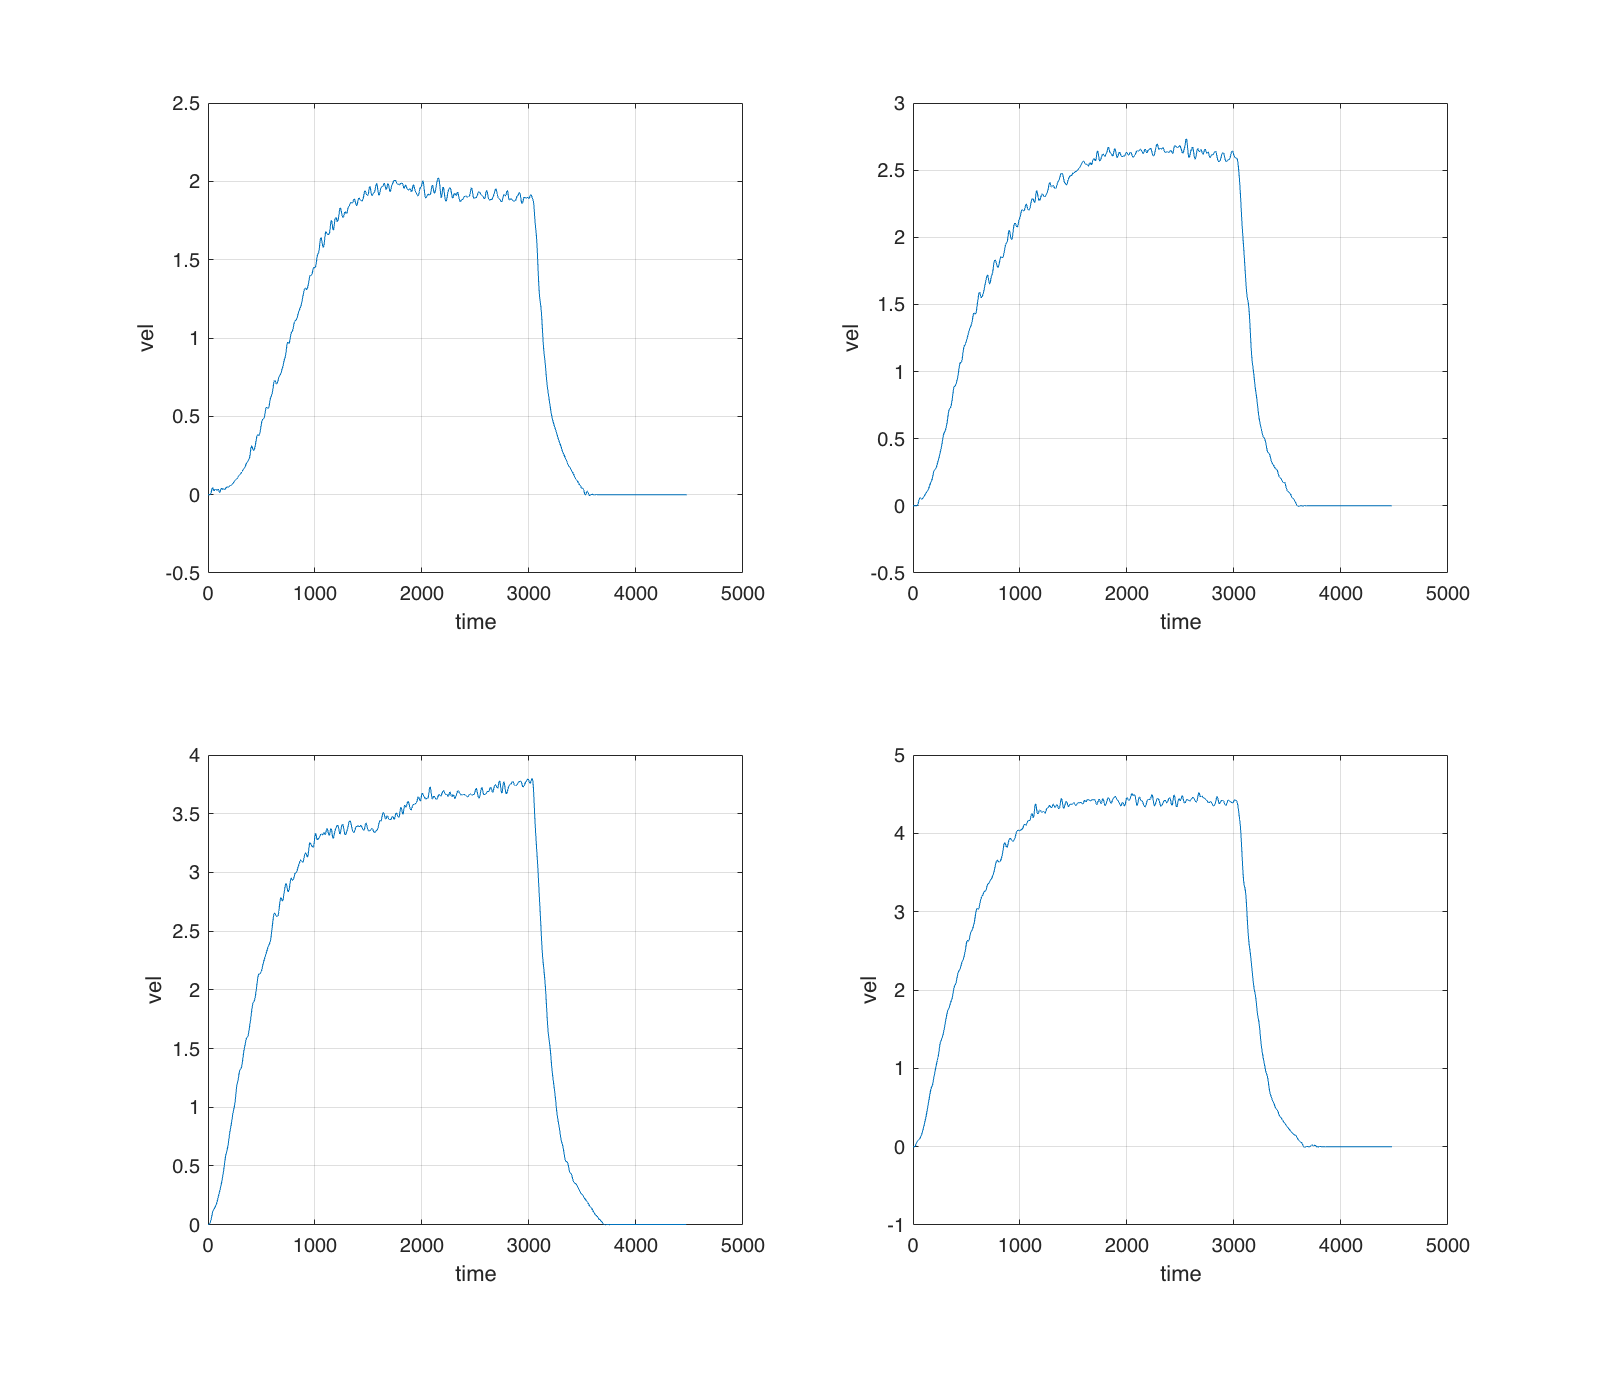

figure('Units','normalized','Position',[0 0 2.0 2.0]);
subplot(2,2,1);
plot(exps.data{4}.vel);grid;xlabel('time');ylabel('vel');
subplot(2,2,2);
plot(exps.data{7}.vel);grid;xlabel('time');ylabel('vel');
subplot(2,2,3);
plot(exps.data{10}.vel);grid;xlabel('time');ylabel('vel');
subplot(2,2,4);
plot(exps.data{14}.vel);grid;xlabel('time');ylabel('vel');

## Poszukiwanie parametrów

Optimization stopped by a plot function or output function.'


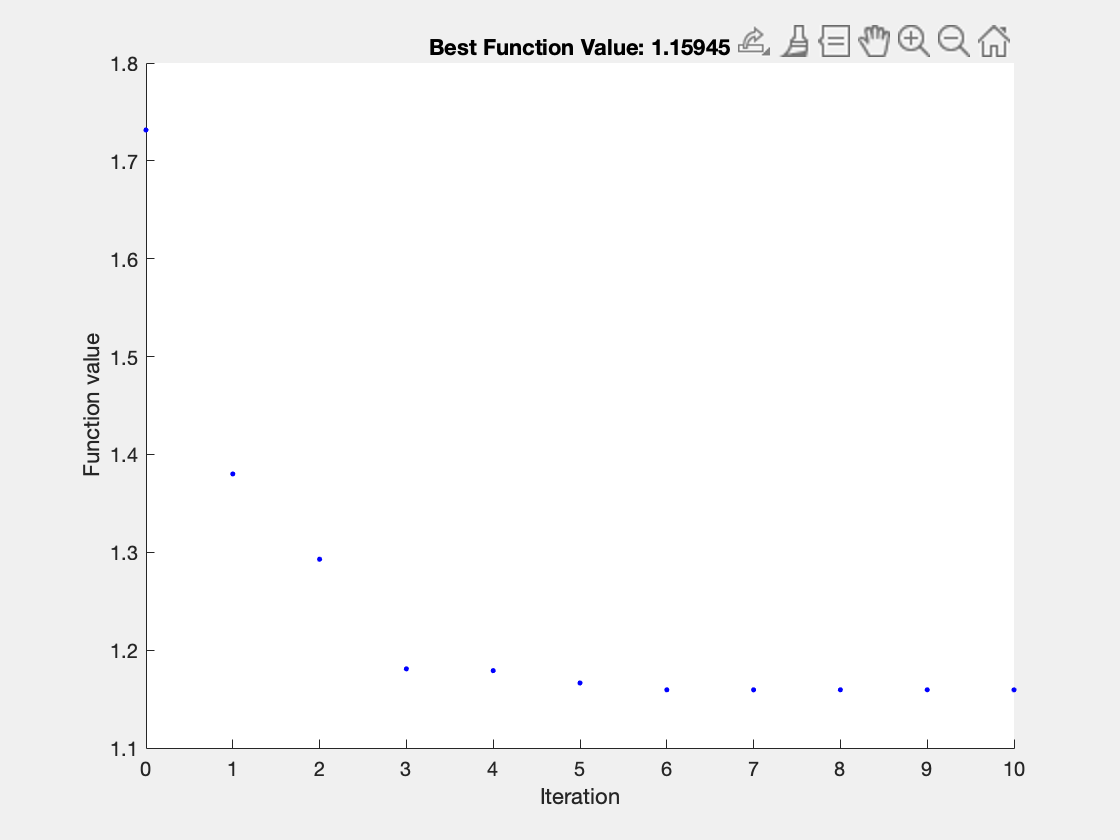

X0 = [0, 0];
options = optimoptions('particleswarm', ...
    'PlotFcn', 'pswplotbestf',...
    'UseParallel', true);

% 'SwarmSize', 50, ...
% 'MaxIterations', 100, ...
rng default
Xopt = particleswarm(@(x) costFun(x, ...
            [exps.dt length(exps.ident.u)*exps.dt], ... % czas
            X0, ...
            exps.ident.u', ...                          % sterowanie
            [inf, 4.416; -inf, 0.0], ...                % ograniczenia na zmienne stanu
            @EVEModel1, ...                             % model
            exps.ident.y), ...                          % dane zalogowane
        5, ...                                          % liczba zmiennych poszukiwanych
        [1e-1, 1e-1, 1e-1, 1e-1, 1e-1], ...             % ograniczenia dolne na zmienne K T1 T2 T3 T4 
        [5, 20, 20, 20, 20], ...                        % K T1 T2 T3 T4
        options);

% 9.2235    4.0238    1.8012    0.4449    1.4281

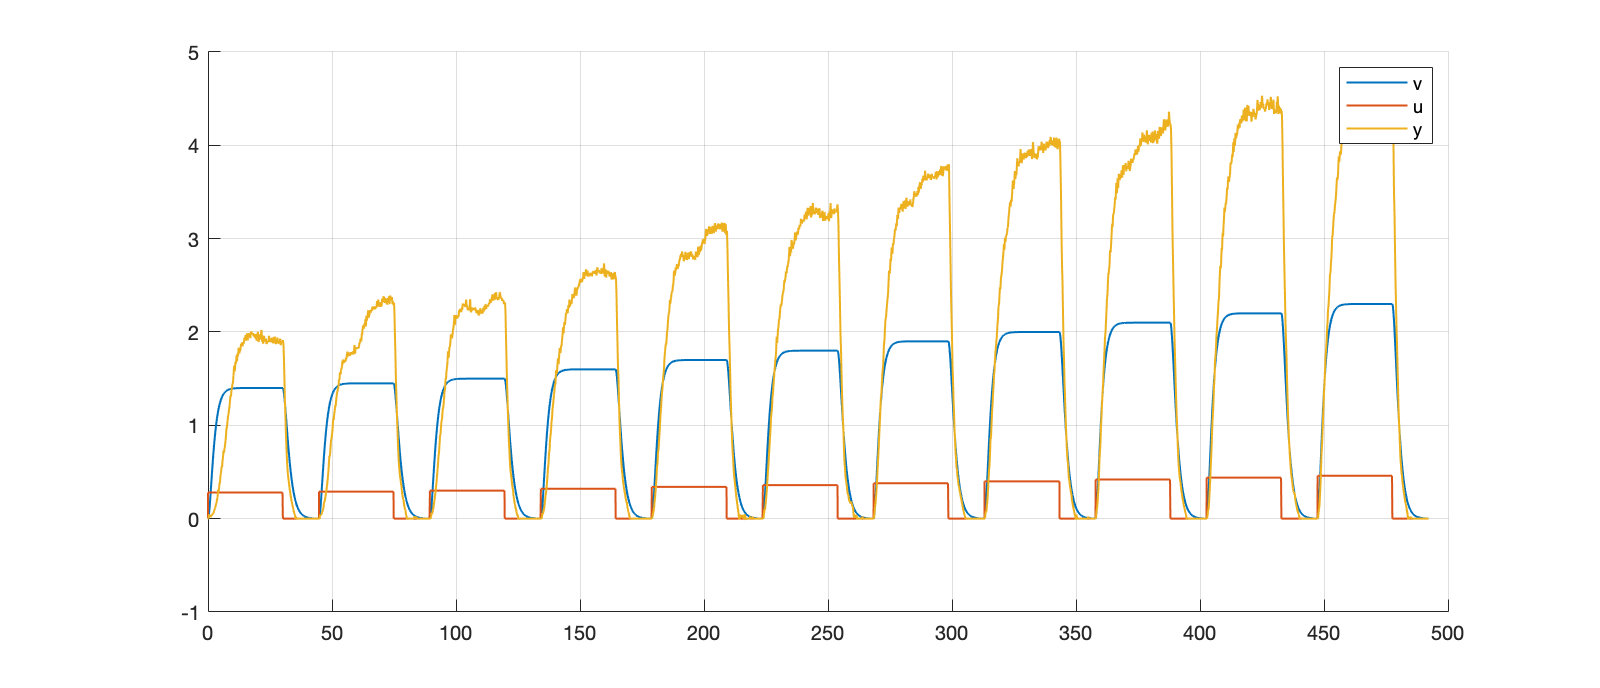

[c, t, x] = costFun(Xopt, ...
    [exps.dt length(exps.ident.u)*exps.dt], X0, ...
    exps.ident.u', ...
    [inf, 4.416; -inf, 0.0], ...
    @EVEModel1, exps.ident.y);
figure('Units','normalized','Position',[0 0 1.0 .5]);
hold on;grid;
plot(t, x(:,2), 'LineWidth', 1);
plot(t, [0; exps.ident.u'],'LineWidth', 1);
plot(t, [0; exps.ident.y'], 'LineWidth', 1');
legend('v', 'u', 'y');
hold off;

## Funkcja kosztu

function [dx] = EVEModel1(t, x, u, params)

    K1 = params(1);
    T1 = params(2);
    T2 = params(3);
    T3 = params(4);
    T4 = params(5);
    
    if any(u(:))
        A = [-(T1+T2)/(T1*T2) -1/(T1*T2); 1 0];
        B = [ K1 / (T1*T2) ; 0];
    else
        A= [-(T3+T4)/(T3*T4) -1/(T3*T4); 1 0];
        B = [ 0 ; 0];
    end

    dx = A * x(:) + B * u(:);
end

function [c, t, x] = costFun(params, tspan, x0, u, bounds, model, x_sim)
    [t, x] = rk4( @(t, x, u) model(t, x, u, params), tspan, x0, u, bounds);
    c = mean( (x(2:end, 2) - x_sim(:)).^2);
end